# Velocity as Opposed to Time For Two Objects of Equal Mass Colliding

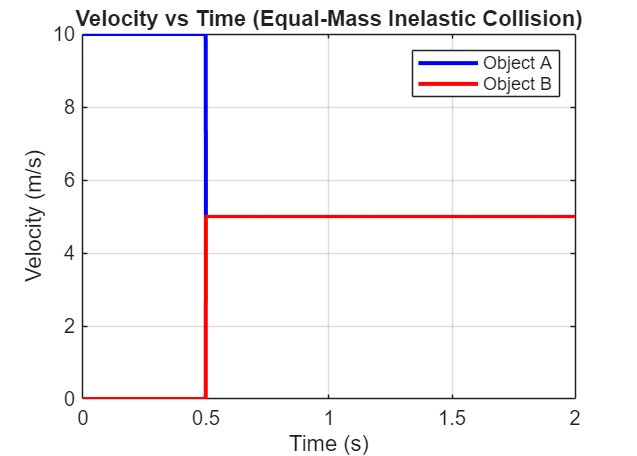

%{
ES115: Velocity as Opposed to Time For Two Objects of Equal Mass Colliding
Author: Jack O'charek
Date: 4-28-26
Purpose:
    Demonstrate inelastic collisions by examining the motion of two
    different objects.
Input: N/A
Output:
    Plot demonstrating the velocity as opposed to time for both objects
Engineering Algorithms:
    Clear screen and delete all variables
    Define masses for both objects (equal)
    Define initial velocities (A moving and B at rest)
    Define the setup for time in the equation
    Prealloctae for equation
    Choose time of collision (0.5 seconds)
    Create simulation loop for - if
    Create plot of velocity over time
%}
clc;
clear;
close all;

mA = 30;   
mB = 30;   

vA0 = 10;  
vB0 = 0;   

dt = 0.001;
t = 0:dt:2;

vA = zeros(size(t));
vB = zeros(size(t));

vA(1) = vA0;
vB(1) = vB0;

t_collision = 0.5;
collided = false;

for i = 1:length(t)-1
    
    if ~collided && t(i) >= t_collision
        collided = true;
        
        v_final = (mA*vA(i) + mB*vB(i)) / (mA + mB);
        
        vA(i:end) = v_final;
        vB(i:end) = v_final;
    end
    
    if ~collided
        vA(i+1) = vA0;
        vB(i+1) = vB0;
    else
        vA(i+1) = vA(i);
        vB(i+1) = vB(i);
    end
end

figure('Position', [300, 100, 700, 500]);

plot(t, vA, 'b', 'LineWidth', 2); hold on;
plot(t, vB, 'r', 'LineWidth', 2);

xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs Time (Equal-Mass Inelastic Collision)');
legend('Object A','Object B');
grid on;